clc;
close all; 
clear all; 

# Bounes 2 by Eldar Mamedov

first we take 2 images with the same background and a twist in it. 

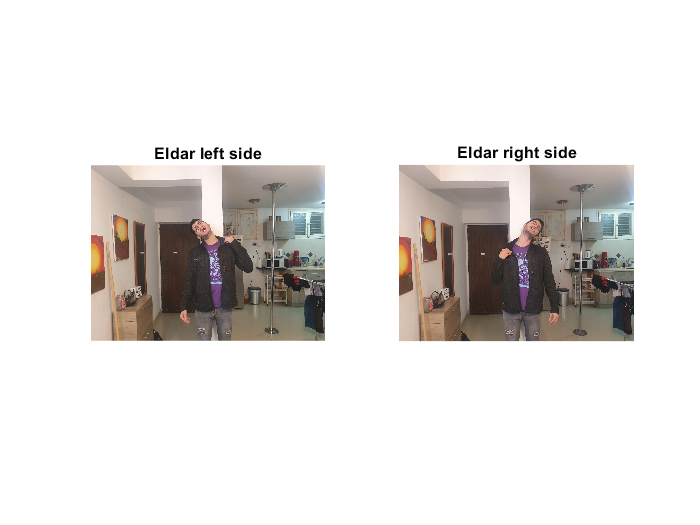

%% Reading the original images  
Eldar_L = imread('Eldar_L.jpeg');
Eldar_R = imread('Eldar_R.jpeg'); 
figure;subplot(1,2,1);
imshow(Eldar_L); title("Eldar left side");
subplot(1,2,2);imshow(Eldar_R); title("Eldar right side");

now we normalize the photos and make hybrid photo of the 2 in grayscale.

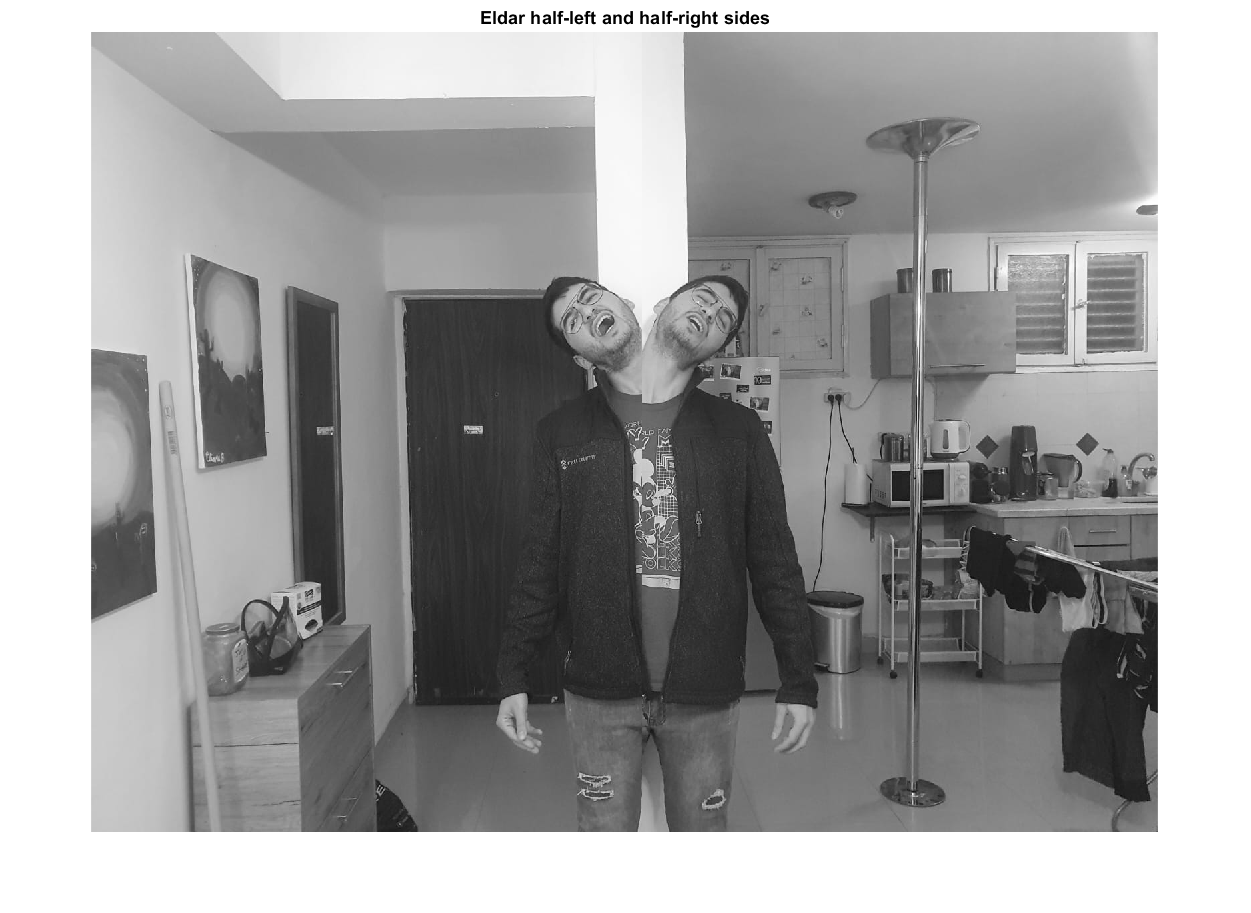

%% ------Slicing the images 
[rows, cols] = size(Eldar_L);
Eldar_L_gray = rgb2gray(Eldar_L); 
Eldar_R_gray = rgb2gray(Eldar_R);
[rows, cols] = size(Eldar_L_gray);
n = cols/2 ;
Eldar_L_R = [Eldar_L_gray(:,1:n+26),Eldar_R_gray(:,n+27:end)];
figure;imshow(Eldar_L_R);title("Eldar half-left and half-right sides");

now we normalized the images of the hybrid left and right 

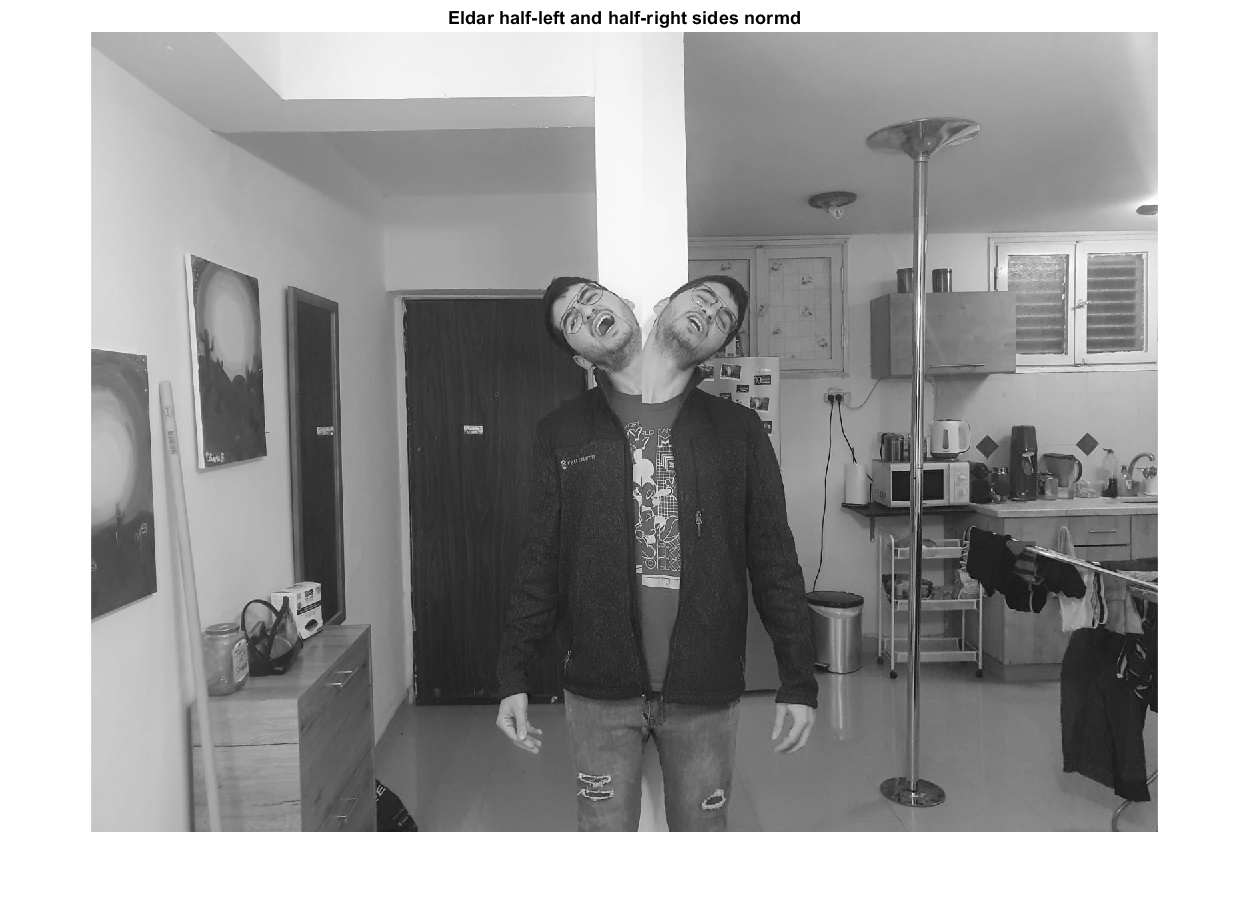

levels = 6; % we will use 5 levels 
Eldar_L_R_norm = dip_GN_imread(Eldar_L_R);
Eldar_L_norm = dip_GN_imread(Eldar_L_gray);
Eldar_R_norm = dip_GN_imread(Eldar_R_gray);
figure;
imshow(Eldar_L_R_norm);title("Eldar half-left and half-right sides normd");

**Creating the Gaussian and Laplacian pyarmids **

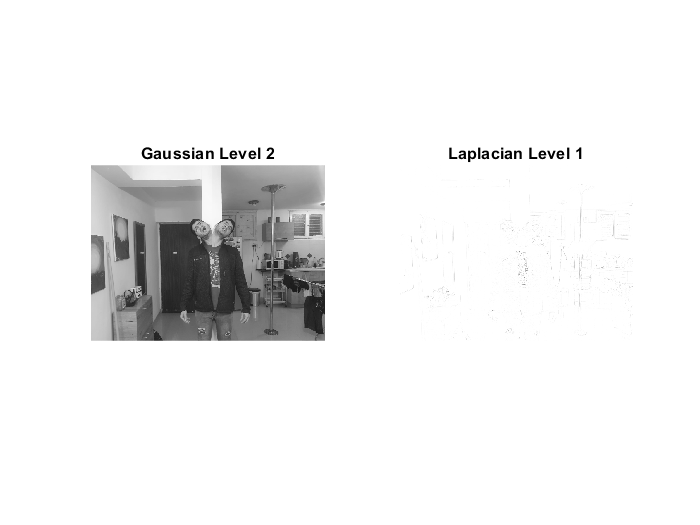

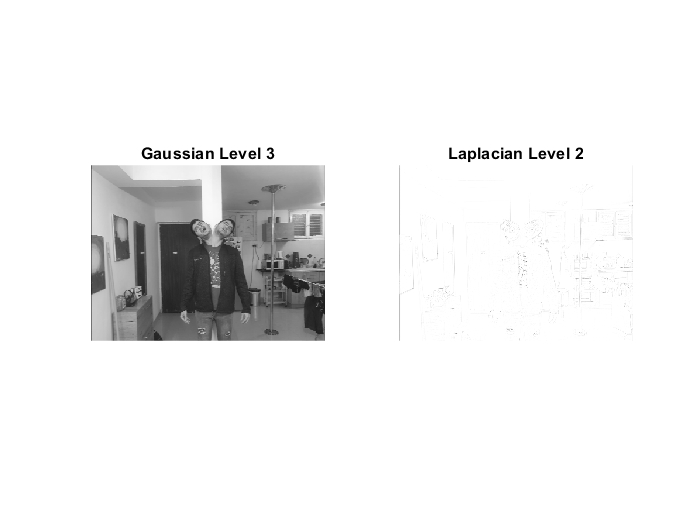

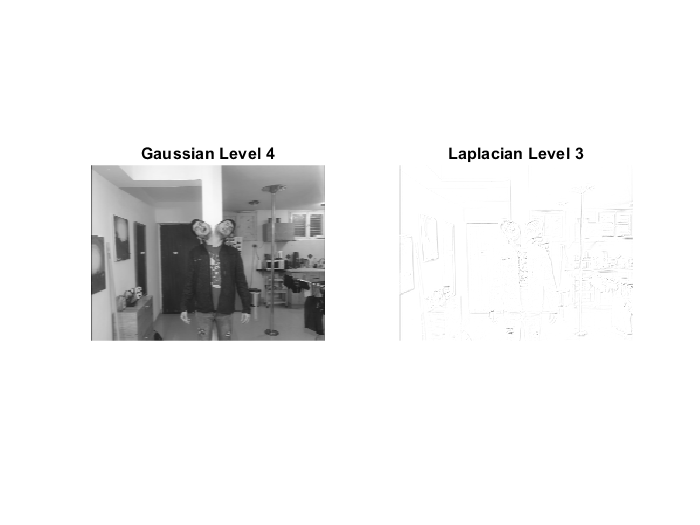

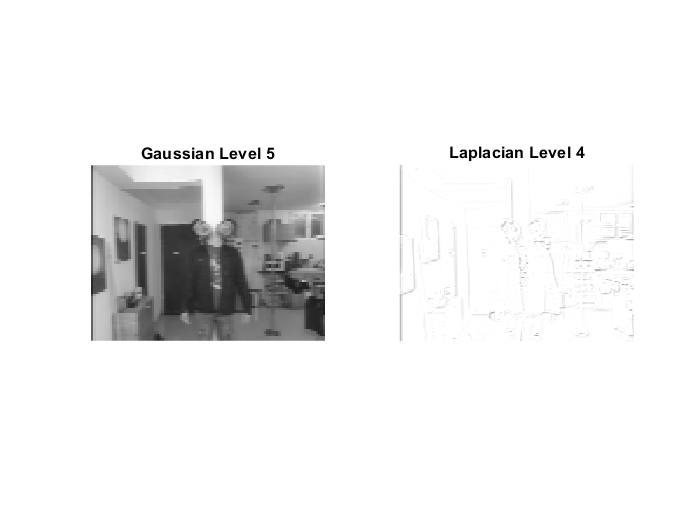

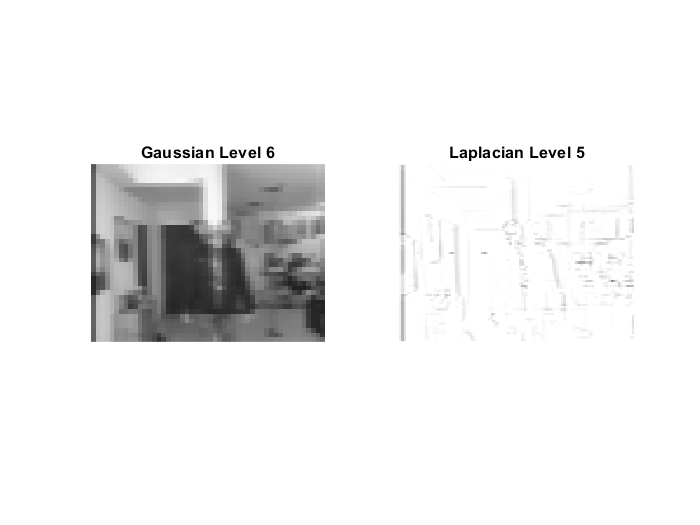

kernal = [1 4 6 4 1]./16; 
pyr_gauss_R_L = cell(1,levels); 
pyr_gauss_R_L{1} = Eldar_L_R_norm;
pyr_lap_R_L = cell(1,levels-1);

for i = 2:levels
   pyr_gauss_R_L{i}= Gaussian_level(pyr_gauss_R_L{i-1},kernal);
   pyr_lap_R_L{i-1} = Laplacian_Level(pyr_gauss_R_L{i-1},pyr_gauss_R_L{i});
   figure;
   subplot(1,2,1);imshow(pyr_gauss_R_L{i});title(sprintf("Gaussian Level %d",i));
   subplot(1,2,2);imshow(1 - pyr_lap_R_L{i-1});title(sprintf("Laplacian Level %d",i-1));
end    

%we do the same for laft and right images
pyr_gauss_R = cell(1,levels); 
pyr_gauss_R{1} = Eldar_R_norm;
pyr_lap_R = cell(1,levels-1);
pyr_gauss_L = cell(1,levels); 
pyr_gauss_L{1} = Eldar_L_norm;
pyr_lap_L = cell(1,levels-1);


for i = 2:levels
   pyr_gauss_R{i}= Gaussian_level(pyr_gauss_R{i-1},kernal);
   pyr_gauss_L{i}= Gaussian_level(pyr_gauss_L{i-1},kernal);
   pyr_lap_R{i-1} = Laplacian_Level(pyr_gauss_R{i-1},pyr_gauss_R{i});
   pyr_lap_L{i-1} = Laplacian_Level(pyr_gauss_L{i-1},pyr_gauss_L{i});
end    

I used a normalized kernel: [1 4 6 4 1]./16.  Convoluted the kernel with the image and down sampled after for gaussian pryarmid,

for the Laplacian pryarmid I up-sampled with reszie function and subtracted. 

this I did for hybrid image as can be seen and also for the left and right imges 

**Rebuilding**

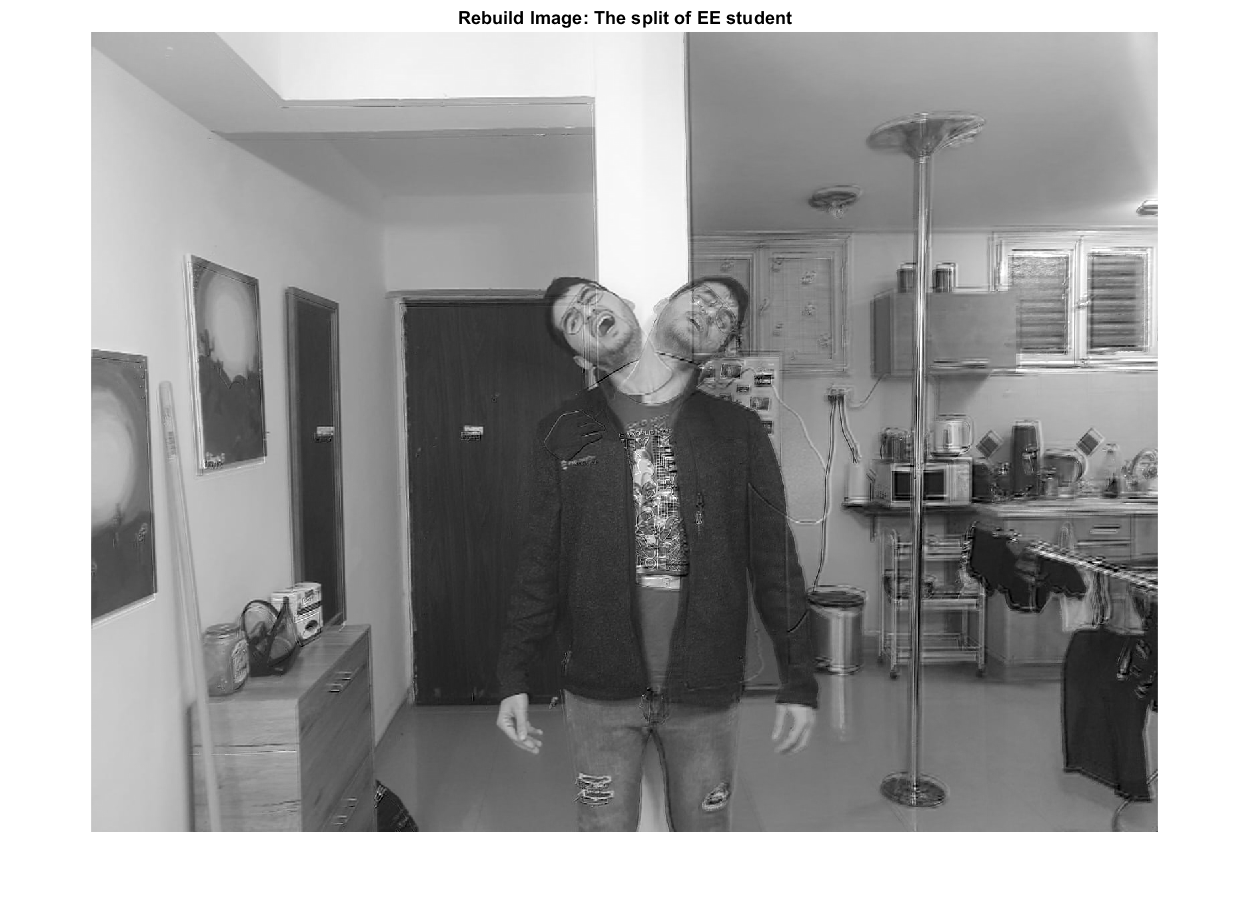

re_build =  pyr_lap_R_L{5} + imresize(pyr_gauss_R_L{6},size(pyr_lap_R_L{5}),'lanczos3');
re_build =  pyr_lap_R_L{4} + imresize(re_build,size(pyr_lap_R_L{4}),'lanczos3');
re_build =  pyr_lap_R_L{3} + imresize(re_build,size(pyr_lap_R_L{3}),'lanczos3');
re_build =  pyr_lap_L{2} + imresize(re_build,size(pyr_lap_R_L{2}),'lanczos3');
re_build =  pyr_lap_R{1} + imresize(re_build,size(pyr_lap_R_L{1}),'lanczos3');
figure;imshow(re_build);title("Rebuild Image: The split of EE student");

rebuilding the imges with the gussian pyarmid as a base and  cascaded the Laplacian pyarmid of the left, right and hybrid to create a masterpiece. 

**Functions **

function gray_scale_image_norm = dip_GN_imread(the_image)
% This function will return normalized gray scale image
    gray_scale_image = double(the_image);
    max_val = max(gray_scale_image(:)); 
    min_val = min(gray_scale_image(:)); 
    gray_scale_image_norm = (gray_scale_image - min_val)./(max_val-min_val);
end

function Gauss_i = Gaussian_level(img,kernal)
%this is a gauss conv with downsampling 
    gauss_i = conv2(img,kernal,'same');
    [rows, cols] = size(gauss_i);
    Gauss_i = gauss_i(1:2:end,1:2:end);
end

function Lap_i = Laplacian_Level(g_i,g_i2)
    B = imresize(g_i2,size(g_i),'lanczos3');
    Lap_i = g_i - B; 
end

